%Fecha de actualización: 19/Septiembre/2023
%clc
%clear all

# Manipulación de archivos y carpetas en MATLAB

El primer paso para lograr un adecuado manejo de archivos en el entorno de programación de MATLAB es aprender a manipular archivos directamente desde el propio programa

Para ello realizaremos los siguientes ejercicios

- *Creación de carpetas*

- *Copiar y mover archivos de directorio*

- *Borrar archivos y carpetas*

- *Descargar archivos de internet*

## °°°Creación de carpetas°°°

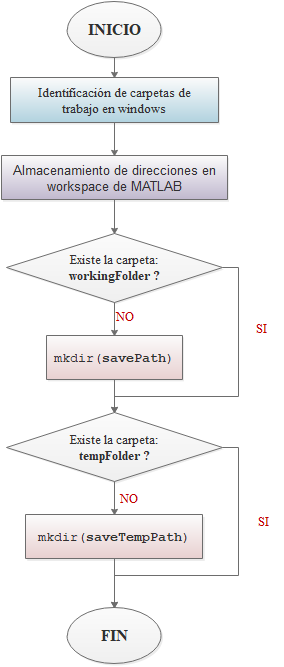

**Figura 1.-** Diagrama de flujo del ejercicio 1

%Siempre te recomiendo que coloques en una variable local de trabajo 
%las siguientes direcciones:

%Dirección raíz de la carpeta de trabajo
    %rootFolder = 'D:\TSISB_IA';
    %rootFolder ='D:\MATLAB_Drive_esc\TSISB_IA';
    %rootFolder ='C:\Users\puma_\Documents\TSISB_IA';

    %Ejercicio 1
    rootFolder ='C:\Users\puma_\Documents\TSISB_IA';
%Dirección de la carpeta local de la práctica
    %workingFolder = '\practica_1';
    %Ejercicio 1
    workingFolder = '\315165805';
    savePath = fullfile(rootFolder,workingFolder);

%Dirección de la carpeta temporal 
    %tempFolder = 'temp';
    %Ejercicio 1
    tempFolder = 'practica_1_Flores';
    saveTempPath = fullfile(rootFolder,workingFolder,tempFolder);
    

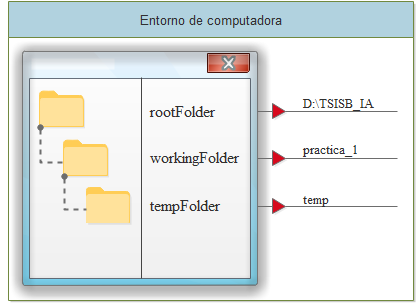

**Figura 2.- **Jerarquia de carpetas de trabajo

%Con la siguiente serie de comandos creas tu carpeta de la práctica:
if ~exist(savePath,'dir')
    [status, message, ~] = mkdir(savePath);
    if status == 0
        disp(message)
    end
end

%Con la siguiente serie de comandos creas tu carpeta de almacenamiento temporal:
if ~exist(saveTempPath,'dir')
    [status, message, ~] = mkdir(saveTempPath);
    if status == 0
        disp(message)
    end
end

### ***** Ejercicio *****

Con la información presentada, crea tu carpeta de trabajo en tu computadora, esta carpeta será donde desarrollaras el contenido de tu práctica 1

Utiliza el siguiente criterio

*Nombre de la carpeta raíz: Número de boleta

*Nombre de la subcarpeta de trabajo: Número de práctica seguido de tu Apellido paterno

## °°° Copiar y mover archivos  de directorio

El siguiente paso será mover un archivo de texto (A_puntos_cos7.txt). Para ello te pido accedas al siguiente enlace de carpeta y descargues el archivo en tu carpeta de descargas

- [Archivos para descargar programa 2](https://comunidadunammx-my.sharepoint.com/:f:/g/personal/laguilarpe_comunidad_unam_mx/EhHL3OJEcQBFpcMQGeAhdSQBako7tuwkpPtgEuPQwAc5-w?e=xuye2N)

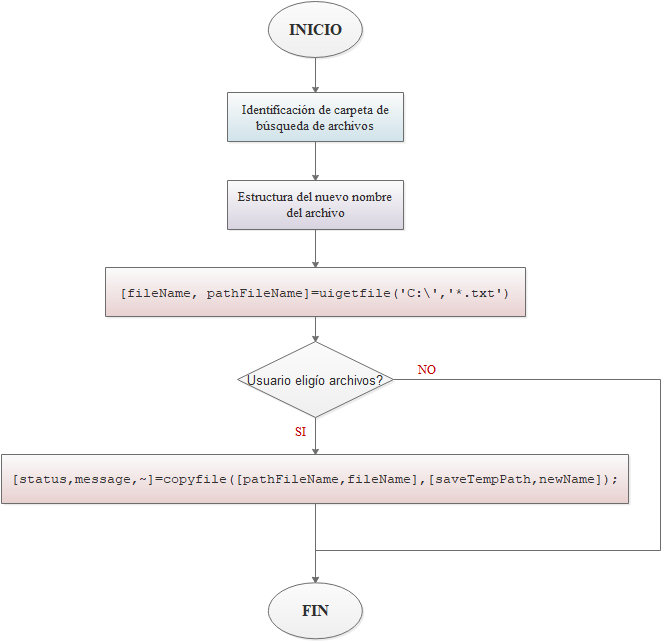

**Figura 3.-** Diagrama de flujo del ejercicio 2

%Nombre nuevo del archivo a copiar/mover

% Coia/mueve el archivo 1 vez

% prefix = ['\' 'A_Puntos_cos7_'];
% i=1;
% incremento = num2str(i);
% sufix = '.txt';
% %Estructura general del archivo nuevo
% newName = [prefix, incremento, sufix]

%Ciclo for para copiar/mover el mismo archivo 3 veces.
prefix = ['\' 'A_Puntos_cos7_'];
sufix = '.txt';
for i = 1:3
    incremento = num2str(i);
    %Estructura general del archivo nuevo
    newName = [prefix, incremento, sufix]


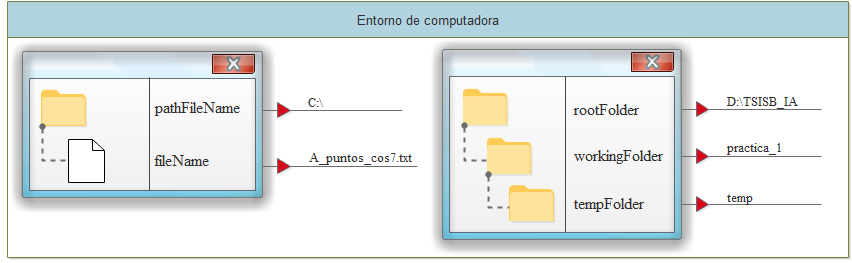

**Figura 4.-** Jerarquia de carpetas de trabajo


%Determinacion del archivo que se va a copiar/mover
[fileName, pathFileName] = uigetfile('C:\','*.txt' );

%Condicional para elección de archivos
if isequal(fileName,0)
   disp('Se canceló la busqueda de archivos');
else
   disp(['El usuario seleccionó el archivo ', fullfile(pathFileName,fileName)]);
   %Con los siguientes comandos se copian el archivo elegido
   [status, message, ~] = copyfile([pathFileName,fileName],[saveTempPath,newName])
    if status == 0
        disp(message)
    else
        disp(['El cual se movio a la dirección ', fullfile(saveTempPath)]);
    end
end
end

newName = '\A_Puntos_cos7_1.txt'

El usuario seleccionó el archivo C:\Users\puma_\Downloads\A_Puntos_cos7.txt


status = logical
   1



message =

  0×0 empty char array



El cual se movio a la dirección C:\Users\puma_\Documents\TSISB_IA\315165805\practica_1_Flores


newName = '\A_Puntos_cos7_2.txt'

El usuario seleccionó el archivo C:\Users\puma_\Downloads\A_Puntos_cos7.txt


status = logical
   1



message =

  0×0 empty char array



El cual se movio a la dirección C:\Users\puma_\Documents\TSISB_IA\315165805\practica_1_Flores


newName = '\A_Puntos_cos7_3.txt'

El usuario seleccionó el archivo C:\Users\puma_\Downloads\A_Puntos_cos7.txt


status = logical
   1



message =

  0×0 empty char array



El cual se movio a la dirección C:\Users\puma_\Documents\TSISB_IA\315165805\practica_1_Flores


### ***** Ejercicio *****

Busca en la ayuda de MATLAB el comando: *"movefile" *y responde las siguientes preguntas

- Cual es la principal diferencia entre copyfile y movefile

- Cuales son los resultados de los flags de cada uno de estos comandos

- Crea un ciclo for donde copies el archivo descargado 3 veces con 3 distintos nombres consecutivos

## °°°Borrar archivos

%Para borrar de manera permanente un archivo, quita el comentario de las
%siguientes dos lineas de comandos
%recycle('off')
%fullfile(saveTempPath)

%delete([fullfile(saveTempPath),newName],'*.txt')
%delete( [tempPath,newName], '*.txt')

%para enviar a la papelera de reciclaje, quita el comentario de las
%siguientes lineas de comandos
recycle('on')
delete( [saveTempPath,newName], '*.txt')

## °°°Descargar archivos de Internet

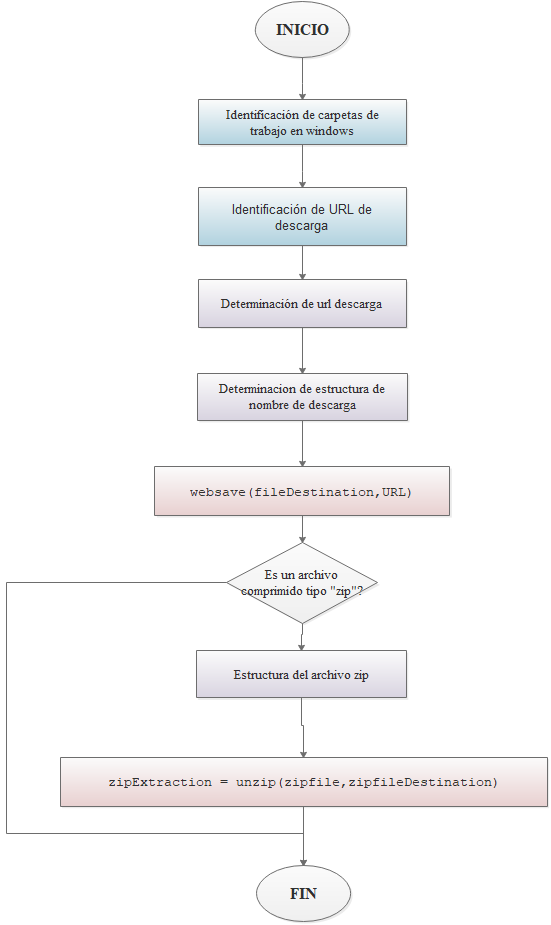

**Figura 5.- ** Diagrama de flujo del ejercicio 3

Para este caso particular, descargaremos los archivos pertenecientes al reto "Computing in Cardiology challenge 2017". Este reto buscaba clasificar señales a partir de su informacion. Puedes encontrar más información en la siguiente web:

- [Web Physionet](https://archive.physionet.org/challenge/2017/)

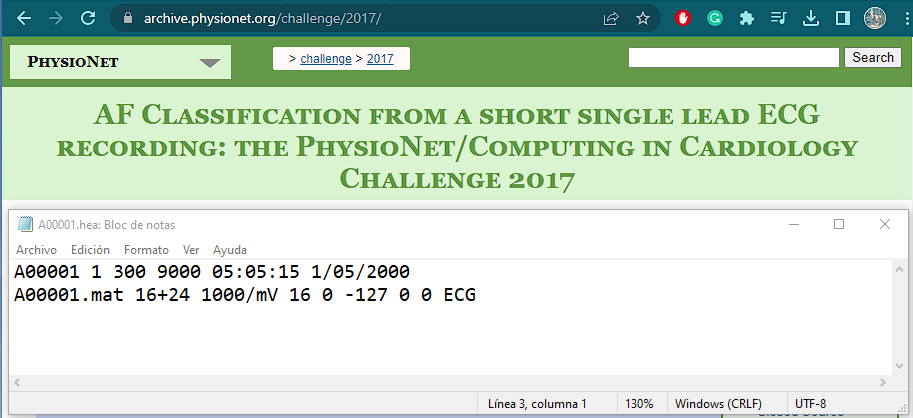

%Designa una variable local donde indicaremos la dirección URL de descarga
%del archivo
url = 'https://archive.physionet.org/challenge/2017/training2017.zip';

%Asigna el nombre del archivo en tu PC
fileName = '\AFClassification';
fileExtension = '.zip';
fileDestination = [saveTempPath fileName fileExtension]

fileDestination = 'C:\Users\puma_\Documents\TSISB_IA\315165805\practica_1_Flores\AFClassification.zip'

disp('Descargando los archivos...')

Descargando los archivos...



%Realiza la descarga del archivo en la dirección especificada
websave(fileDestination,url)

ans = 'C:\Users\puma_\Documents\TSISB_IA\315165805\practica_1_Flores\AFClassification.zip'

disp('Archivos descargados')

Archivos descargados



%Estructura del archivo *.zip
zipfile = fileDestination;
zipFileDestination = [saveTempPath '\unzipDir\'];
%Se crea una carpeta para descomprimir los archivos dentro de la carpeta
%temporal
if ~exist(zipFileDestination,'dir')
    [status, message, ~] = mkdir(zipFileDestination);
end

%Se realiza la extracción del archivo deseado
zipExtraction = unzip(zipfile,zipFileDestination);

***** Ejercicio *****

Con ayuda del comando delete y rmdir borra todos los archivos que terminen en *.hea

## **°°°Eliminar archivos**

%Especifica la carpeta donde se encuentran los archivos
saveTempPath
PathFileTo='\unzipDir\training2017'

saveTempPath = 'C:\Users\puma_\Documents\TSISB_IA\315165805\practica_1_Flores'

carpeta= [saveTempPath PathFileTo]

PathFileTo = '\unzipDir\training2017'

% Obtiene una lista de archivos en la carpeta

carpeta = 'C:\Users\puma_\Documents\TSISB_IA\315165805\practica_1_Flores\unzipDir\training2017'

files = dir(fullfile(carpeta, '*.hea'));

% Recorre la lista de archivos
for i = 1:length(files)
    nombreArchivo = files(i).name;
    
    % Verifica si el archivo termina en ".hea"
    if endsWith(nombreArchivo, '.hea')
        % Crea la ruta completa del archivo
        archivoCompleto = fullfile(carpeta, nombreArchivo);
        
        % Elimina el archivo
        delete(archivoCompleto);
    end
end


`Si quieres eliminar el directorio o carpeta después de transferir los archivos .mat a otro. En caso contrario no quite ni el "%"`

%rmdir(carpeta,'s');